## Lab 6: MATLAB CODE AUTHOR: TOMOKI KOIKE

clear all 
close all
clc

% Loading the data files 
file1 = readmatrix('vel_calibration.xlsx');
file2 = readmatrix('lift_drag_calibration.xlsx');
file3 = rmmissing(readmatrix('plates_data.xlsx'));
file4 = rmmissing(readmatrix("cylinder_data.xlsx"));
file5 = rmmissing(readmatrix("airfoil_data.xlsx"));
file6 = readmatrix("dimensions.xlsx");
file6(isnan(file6)) = 0;  % Replacing NaN with 0

% Setting necessary constants
rho = 1.225;  % Desity of air at standard condition [kg/m^3]
visc = 1.789*10^(-5);  % Viscosity of air at standard conditions [Pa-s]

% From file1 get the calibrated dynamic pressures and velocities 
% Dynamic pressures [Pa]
q_10to30 = file1(:,2)*1000; 
% Velocities 
vel_10to30 = file1(:,4);

% From file 6 obtain the dimensions for each object to calculate the
% Reynolds number
c_horzPlate = file6(1,4);  % Horizontal plate
c_vertPlate = file6(2,5);  % Vertical plate
c_smoothCydSmall = file6(3,3); % Smooth cylinder small
c_smoothCydBig = file6(4,3);  % Smooth Cylinder Big
c_roughCyd = file6(5,3);  % Rough cyllinder
c_airfoil = file6(6,3);  % Airfoil

% Finding the Reynolds number for each object
syms U c
Re = @(U, c) rho.*U*c/visc;
% Horizontal Plate
Re_horzPlate_10to30 = Re(vel_10to30, c_horzPlate);
% Vertical Plate
Re_vertPlate_10to30 = Re(vel_10to30, c_vertPlate);
% Smooth cylinder small 
Re_smoothCydSmall_10to30 = Re(vel_10to30, c_smoothCydSmall);
% Smooth cylinder Big
Re_smoothCydBig_10to30 = Re(vel_10to30, c_smoothCydBig);
% Rough Cylinder
Re_roughCyd_10to30 = Re(vel_10to30, c_roughCyd);
% Airfoil
Re_airfoil_10to30 = Re(vel_10to30, c_airfoil);

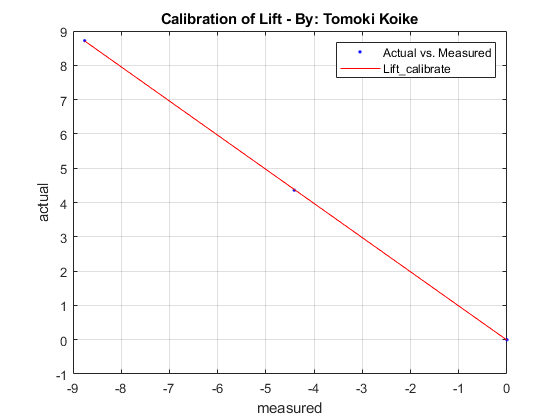

% Finding the scale factor from the lift and drag calibration
% Lift
actual_L = file2(:,1);
measured_L = file2(:,2);
% Drag
actual_D = file2(:,3);
measured_D = file2(:,4);

% Fitting the calibration data to get scale factor
% Lift
[fitresult_L, gof_L] = dataFit(measured_L, actual_L, 'lift');

disp(fitresult_L);

     Linear model Poly1:
     fitresult_L(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.9958  (-1.048, -0.9438)
       p2 =    -0.01259  (-0.3073, 0.2822)


gof_L_mat = cell2mat(struct2cell(gof_L));  % Convert structure to matrix
% Printing out the standard deviation for this polynomial
fprintf('\nThis fitted polynomial curve for lift has a STD of %.5e.', gof_L_mat(1,1));  


This fitted polynomial curve for lift has a STD of 6.43493e-04.

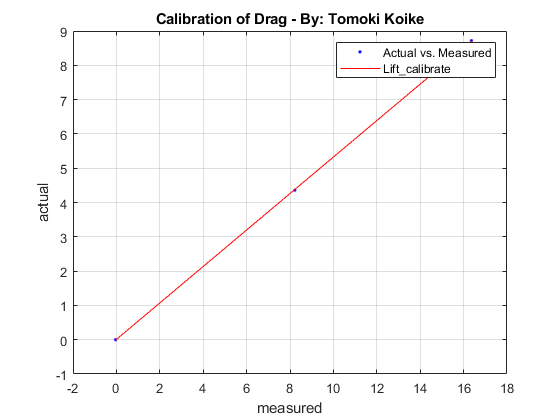

coeffs_L = coeffvalues(fitresult_L);  % Obtaining the coefficients

a_L = coeffs_L(1);
b_L = coeffs_L(2);

% Drag
[fitresult_D, gof_D] = dataFit(measured_D, actual_D, 'drag');

disp(fitresult_D);

     Linear model Poly1:
     fitresult_D(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.5317  (0.5034, 0.5601)
       p2 =    0.008532  (-0.291, 0.308)


gof_D_mat = cell2mat(struct2cell(gof_D));  % Convert structure to matrix
% Printing out the standard deviation for this polynomial
fprintf('\nThis fitted polynomial curve for drag has a STD of %.5e.', gof_D_mat(1,1));  


This fitted polynomial curve for drag has a STD of 6.68240e-04.

coeffs_D = coeffvalues(fitresult_D);  % Obtaining the coefficients

a_D = coeffs_D(1);
b_D = coeffs_D(2);

% Defining a equation expression for lift and drag scaling
% Lift
syms lift 
scale_lift = @(lift) a_L*lift + b_L;
% Drag
syms drag
scale_drag = @(drag) a_D*drag + b_D;


% Calculating each drag coeeficients 
% Horizontal Plate
standDrag = scale_drag(lb2N(file3(1:5,4)));  % Drag for the stand part
Cd_horzPlate_10to30 = calDragCoeff(scale_drag(lb2N(file3(6:10,4))-standDrag), ...
    q_10to30, c_horzPlate);
% Vertical Plate
Cd_vertPlate_10to30 = calDragCoeff(scale_drag(lb2N(file3(11:15,4))-standDrag), ...
    q_10to30, c_vertPlate);
% Smooth Cylinder small
Cd_smoothCydSmall_10to30 = calDragCoeff(scale_drag(lb2N(file4(1:5,4))), q_10to30, ... 
    c_smoothCydSmall);
% Smooth Cylinder Big
standDrag = scale_drag(lb2N(file4(6:10,4)));  % Drag for the stand part
Cd_smoothCydBig_10to30 = calDragCoeff(scale_drag(lb2N(file4(11:15,4))-standDrag),...
    q_10to30, c_smoothCydBig);
% Rough cylinder
Cd_roughCyd_10to30 = calDragCoeff(scale_drag(lb2N(file4(16:20,4))-standDrag),...
    q_10to30, c_roughCyd);
% Airfoil leading edge
standDrag = scale_drag(lb2N(file5(1:5,4)));  % Drag for the stand part
Cd_airfoil_LE = calDragCoeff(scale_drag(lb2N(file5(6:10,4))-standDrag),...
    q_10to30, c_airfoil);
% Airfoil trailing edge
Cd_airfoil_TE = calDragCoeff(lb2N(scale_drag(file5(11:15, 4))-standDrag),...
    q_10to30, c_airfoil);

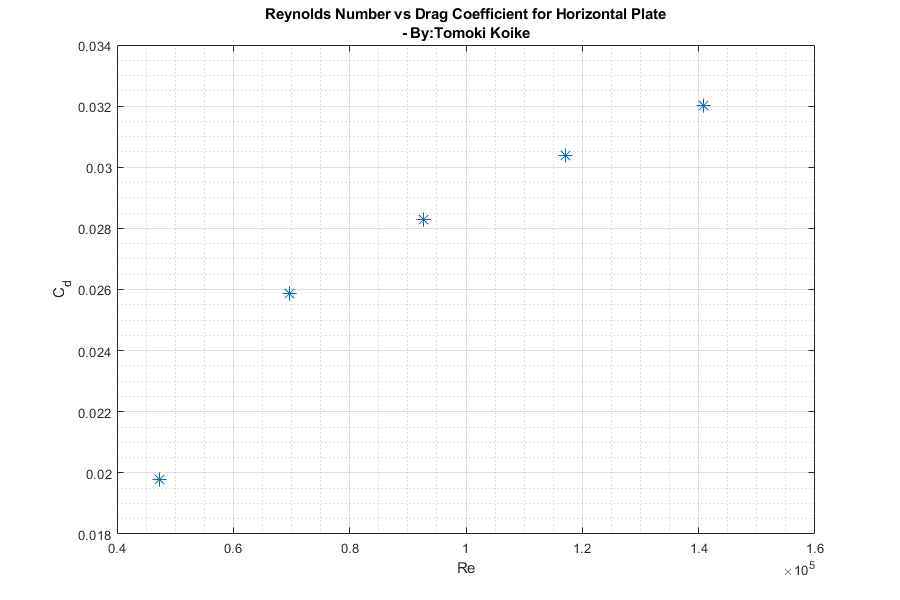

% Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(Re_horzPlate_10to30, Cd_horzPlate_10to30, '*', 'MarkerSize', 10)
title({'Reynolds Number vs Drag Coefficient for Horizontal Plate',['- By:' ...
    'Tomoki Koike']})
xlabel('Re')
ylabel('C_d')
grid on
grid minor
box on

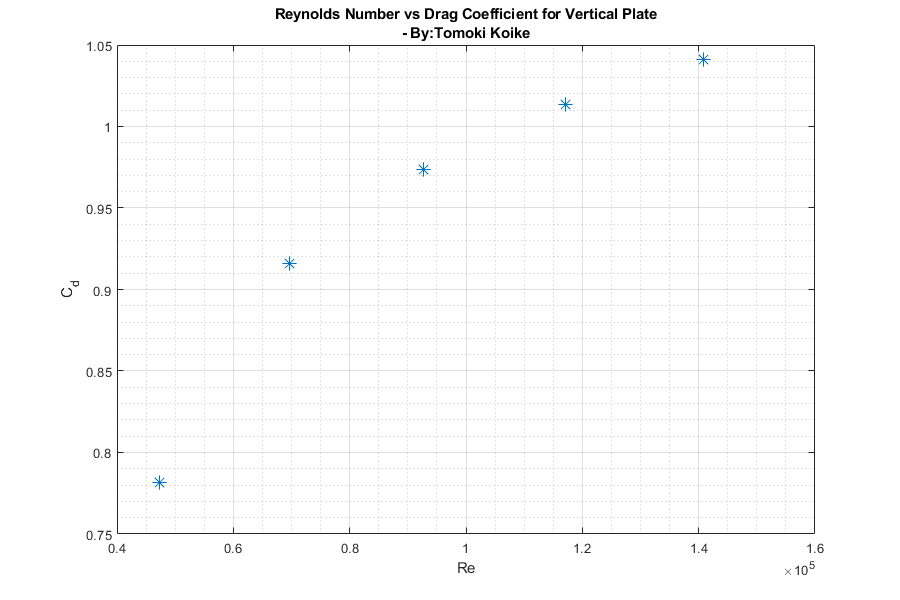


figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(Re_vertPlate_10to30, Cd_vertPlate_10to30, '*', 'MarkerSize', 10)
title({'Reynolds Number vs Drag Coefficient for Vertical Plate',['- By:' ...
    'Tomoki Koike']})
xlabel('Re')
ylabel('C_d')
grid on
grid minor
box on

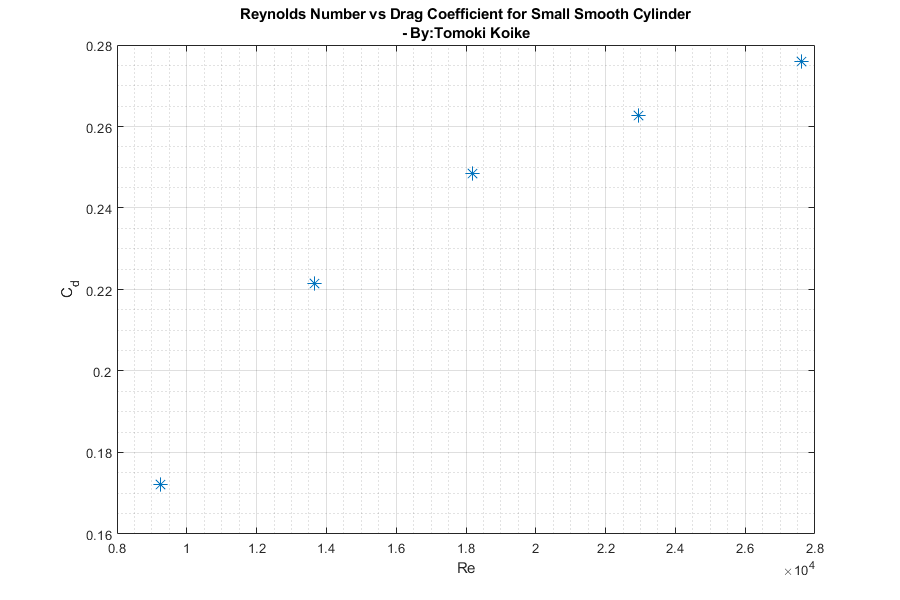


figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(Re_smoothCydSmall_10to30, Cd_smoothCydSmall_10to30, '*', 'MarkerSize', 10)
title({'Reynolds Number vs Drag Coefficient for Small Smooth Cylinder',['- By:' ...
    'Tomoki Koike']})
xlabel('Re')
ylabel('C_d')
grid on
grid minor
box on

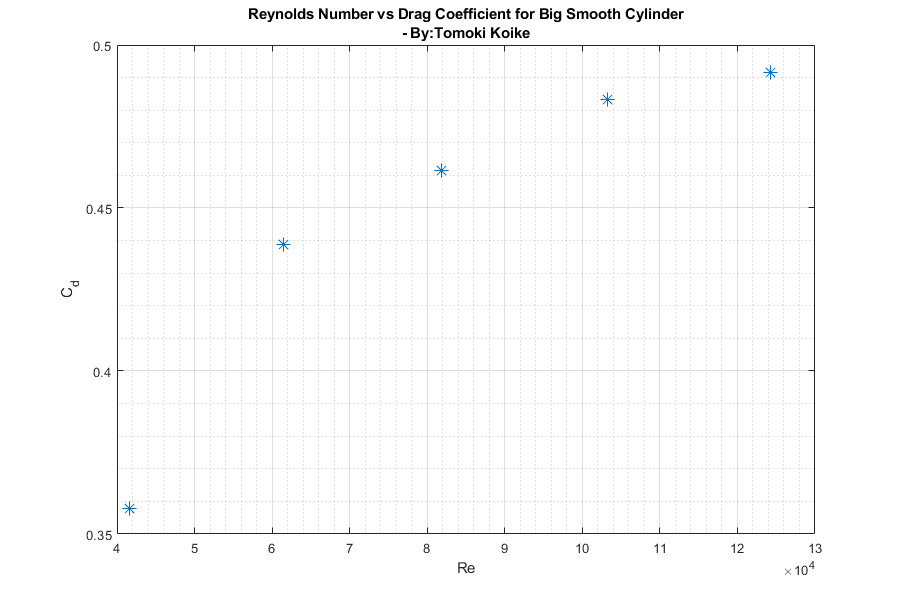


figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(Re_smoothCydBig_10to30, Cd_smoothCydBig_10to30, '*', 'MarkerSize', 10)
title({'Reynolds Number vs Drag Coefficient for Big Smooth Cylinder',['- By:' ...
    'Tomoki Koike']})
xlabel('Re')
ylabel('C_d')
grid on
grid minor
box on

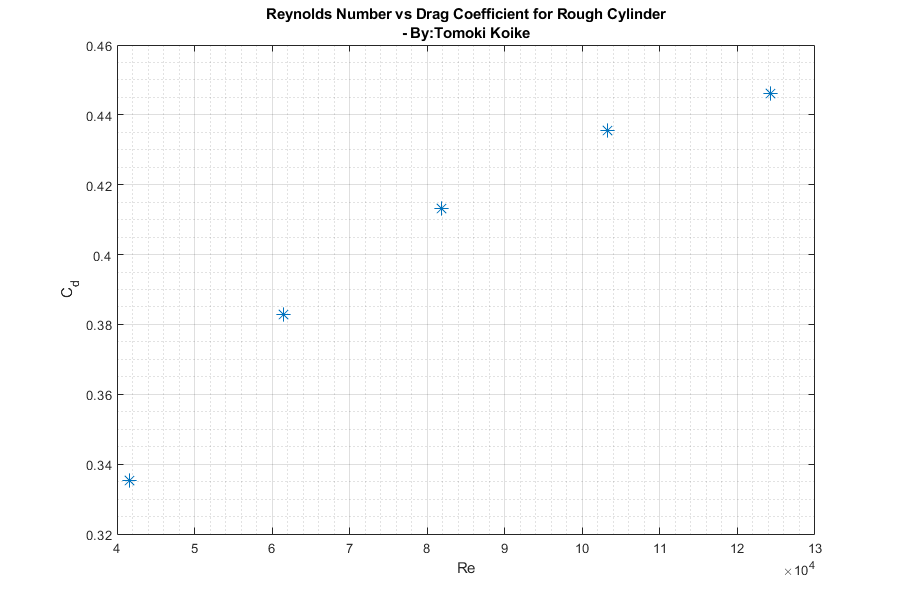


figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(Re_roughCyd_10to30, Cd_roughCyd_10to30, '*', 'MarkerSize', 10)
title({'Reynolds Number vs Drag Coefficient for Rough Cylinder',['- By:' ...
    'Tomoki Koike']})
xlabel('Re')
ylabel('C_d')
grid on
grid minor
box on

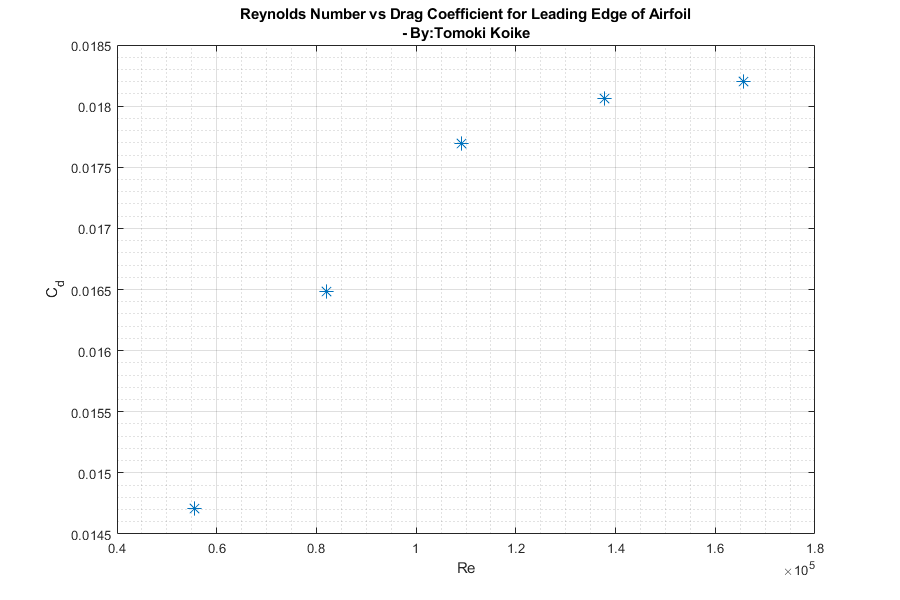


figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(Re_airfoil_10to30, Cd_airfoil_LE, '*', 'MarkerSize', 10)
title({'Reynolds Number vs Drag Coefficient for Leading Edge of Airfoil',['- By:' ...
    'Tomoki Koike']})
xlabel('Re')
ylabel('C_d')
grid on
grid minor
box on

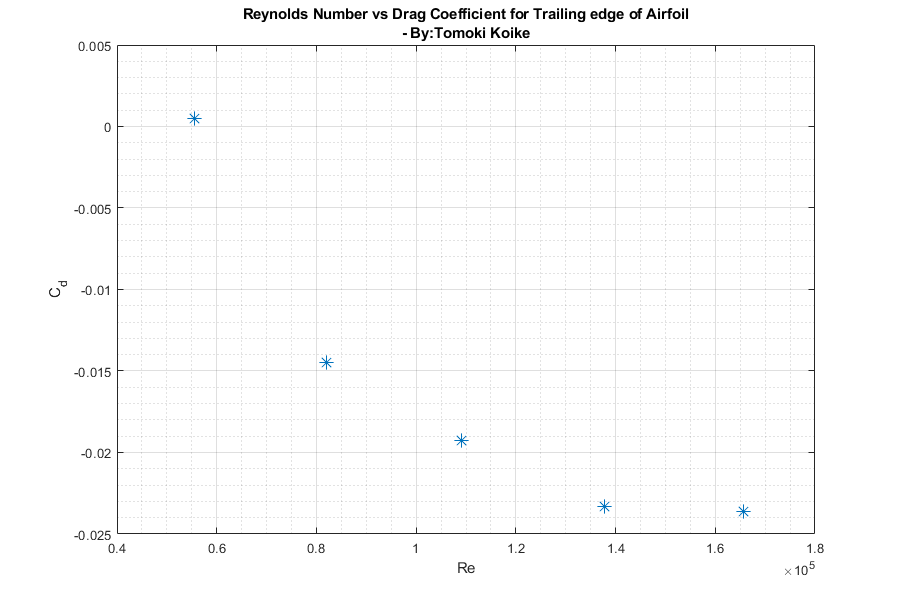


figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(Re_airfoil_10to30, Cd_airfoil_TE, '*', 'MarkerSize', 10)
title({'Reynolds Number vs Drag Coefficient for Trailing edge of Airfoil',['- By:' ...
    'Tomoki Koike']})
xlabel('Re')
ylabel('C_d')
grid on
grid minor
box on

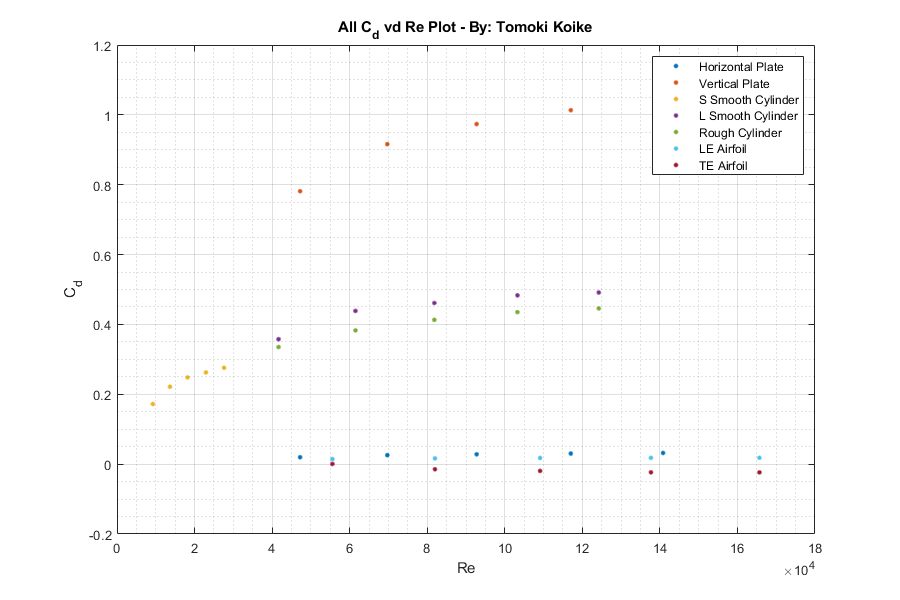


figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(Re_horzPlate_10to30, Cd_horzPlate_10to30, '.', 'MarkerSize', 10)
title('All C_d vd Re Plot - By: Tomoki Koike')
xlabel('Re')
ylabel('C_d')
hold on
plot(Re_vertPlate_10to30, Cd_vertPlate_10to30, '.', 'MarkerSize', 10)
plot(Re_smoothCydSmall_10to30, Cd_smoothCydSmall_10to30, '.', 'MarkerSize', 10)
plot(Re_smoothCydBig_10to30, Cd_smoothCydBig_10to30, '.', 'MarkerSize', 10)
plot(Re_roughCyd_10to30, Cd_roughCyd_10to30, '.', 'MarkerSize', 10)
plot(Re_airfoil_10to30, Cd_airfoil_LE, '.', 'MarkerSize', 10)
plot(Re_airfoil_10to30, Cd_airfoil_TE, '.', 'MarkerSize', 10)
hold off
grid on
grid minor
box on
legend('Horizontal Plate', 'Vertical Plate', 'S Smooth Cylinder', 'L Smooth Cylinder', ...
    'Rough Cylinder', 'LE Airfoil', 'TE Airfoil')

### FUNCTIONS

function [fitresult, gof] = dataFit(measured, actual, type)
    %DATAFIT(MEASURED,ACTUAL)
    %  Create a fit.
    %
    %  Data for 'Lift_calibrate' fit:
    %      X Input : measured_L
    %      Y Output: actual_L
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %  See also FIT, CFIT, SFIT.
    
    %% Fit: 'Lift_calibrate'.
    [xData, yData] = prepareCurveData( measured, actual);
    
    % Set up fittype and options.
    ft = fittype( 'poly1' );
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft );
    
    % Plot fit with data.
    figure( 'Name', 'Lift_calibrate' );
    h = plot( fitresult, xData, yData );
    if type == 'lift'
        title('Calibration of Lift - By: Tomoki Koike')
    else
        title('Calibration of Drag - By: Tomoki Koike')
    end
    legend( h, 'Actual vs. Measured', 'Lift_calibrate', 'Location', 'NorthEast', 'Interpreter', 'none' );
    % Label axes
    xlabel( 'measured', 'Interpreter', 'none' );
    ylabel( 'actual', 'Interpreter', 'none' );
    grid on
end

function Cd = calDragCoeff(D, dynP, l)
    % Function to compute the drag coefficient 
    Cd = D./dynP/l;
end

function F = lb2N(f)
    % Function to convert pounds to Newtons
    F = f ./ 0.22480894244318;
end